clear all
syms a_0 a_1 a_2 a_3 b_0 b_1 c_0 c_1 c_2 c_3
syms q_p q_k v
syms t_a t_c t_k t_b
syms dq_k dq_p


t_c = t_k-t_b;

A = a_0 - q_p;

B = a_1 - dq_p;

C = a_0 + a_1*t_a + a_2*(t_a)^2 + a_3*(t_a)^3 - b_0 - b_1*t_a;

D = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - b_1;

E = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2;

F = b_1 - v;

G = b_0 + b_1*t_c - c_0 - c_1*t_c - c_2*(t_c)^2 - c_3*(t_c)^3;
 
H = b_1 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2;

I = c_0 + c_1*t_k + c_2*(t_k)^2 + c_3*(t_k)^3 -q_k;

J = c_1 + 2*c_2*t_k + 3*c_3*(t_k)^2 - dq_k;

[Z] = solve(A==0, B==0, C==0, D==0, E==0, F==0, G==0, H==0, I==0, J==0 ,a_0, a_1, a_2, a_3, b_0, b_1, c_0, c_1, c_2, c_3);

solved = Z;
q_p_1 = 0;          % pozycja początkowa przegubu nr 1 [rad]
dq_p_1 = 0.0;       % prędkość początkowa przegubu nr 1 [rad]
q_k_1 = 1/2 * pi;   % pozycja końcowa przegubu nr 1 [rad/s]
dq_k_1 = 0.1;       % prędkość końcowa przegubu nr 1 [rad/s]
Tk_1 = 10;          % Czas trwania ruchu przegubu [s]
Ta_1 = 4;           % Czas trwania fazy przyspieszania [s]
Tb_1 = 4;           % Czas trwania fazy hamowania [s]
dt_1 = 0.01;        % Krok czasowy [s]    
V_1 = 0.2;          % Prędkość przegubu w fazie drugiej [rad/s]
[q_1,dq_1,ddq_1, t_1] = Trajectory_Generation(solved, q_p_1, dq_p_1,...
q_k_1, dq_k_1, Tk_1, Ta_1, Tb_1, dt_1, V_1);

q_1 = double(q_1);
dq_1 = double(dq_1);
ddq_1 = double(ddq_1);



q_p_2 = 0;          % pozycja początkowa przegubu nr 1 [rad]
dq_p_2 = 0.0;       % prędkość początkowa przegubu nr 1 [rad]
q_k_2 = 3/2 * pi;   % pozycja końcowa przegubu nr 1 [rad/s]
dq_k_2 = 0.1;       % prędkość końcowa przegubu nr 1 [rad/s]
Tk_2 = 10;          % Czas trwania ruchu przegubu [s]
Ta_2 = 2;           % Czas trwania fazy przyspieszania [s]
Tb_2 = 4;           % Czas trwania fazy hamowania [s]
dt_2 = 0.01;        % Krok czasowy [s]   
V_2 = 0.5;          % Prędkość przegubu w fazie drugiej [rad/s]
[q_2,dq_2,ddq_2, t_2] = Trajectory_Generation(solved, q_p_2, dq_p_2, ...
    q_k_2, dq_k_2, Tk_2, Ta_2, Tb_2, dt_2, V_2);

q_2 = double(q_2);
dq_2 = double(dq_2);
ddq_2 = double(ddq_2);

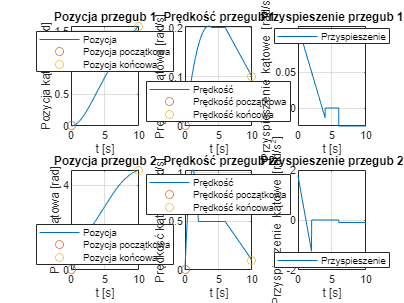

figure;
subplot(2, 3, 1);
plot(t_1, q_1, t_1(1), q_p_1, 'o', Tk_1, q_k_1, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 1')
xlabel('t [s]')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 3, 2);
plot(t_1, dq_1, t_1(1), dq_p_1, 'o', Tk_1, dq_k_1, 'o')
legend('Prędkość', 'Prędkość początkowa', 'Prędkość końcowa', "Location","best")
title('Prędkość przegub 1')
xlabel('t [s]')
ylabel('Prędkość kątowa [rad/s]')
grid on
axis auto

subplot(2, 3, 3);
plot(t_1, ddq_1)
legend('Przyspieszenie', "Location","best")
title('Przyspieszenie przegub 1')
xlabel('t [s]')
ylabel('Przyspieszenie kątowe [rad/s{^2}]')
grid on
axis auto

subplot(2, 3, 4);
plot(t_2, q_2, t_2(1), q_p_2, 'o', Tk_2, q_k_2, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 2')
xlabel('t [s]')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 3, 5);
plot(t_2, dq_2, t_2(1), dq_p_2, 'o', Tk_2, dq_k_2, 'o')
legend('Prędkość', 'Prędkość początkowa', 'Prędkość końcowa', "Location","best")
title('Prędkość przegub 2')
xlabel('t [s]')
ylabel('Prędkość kątowa [rad/s]')
grid on
axis auto

subplot(2, 3, 6);
plot(t_2, ddq_2)
legend('Przyspieszenie', "Location","best")
title('Przyspieszenie przegub 2')
xlabel('t [s]')
ylabel('Przyspieszenie kątowe [rad/s{^2}]')
grid on
axis auto

m1 = 2.5;
m2 = 1.5;
L1 = 0.6;
L2 = 0.5;

[u] = dynamics_model(q_1, q_2, dq_1, dq_2, ddq_1, ddq_2, m1, m2, L1, L2);
u_1 = u(1, :);
u_2 = u(2, :);

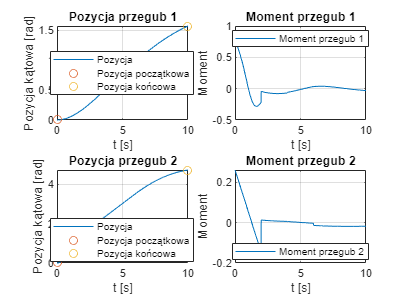

figure;
subplot(2, 2, 1);
plot(t_1, q_1, t_1(1), q_p_1, 'o', Tk_1, q_k_1, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 1')
xlabel('t [s]')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 2, 2);
plot(t_1, u_1)
legend('Moment przegub 1', "Location","best")
title('Moment przegub 1')
xlabel('t [s]')
ylabel('Moment')
grid on
axis auto

subplot(2, 2, 3);
plot(t_2, q_2, t_2(1), q_p_2, 'o', Tk_2, q_k_2, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 2')
xlabel('t [s]')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 2, 4);
plot(t_2, u_2)
legend('Moment przegub 2', "Location","best")
title('Moment przegub 2')
xlabel('t [s]')
ylabel('Moment')
grid on
axis auto

q0 = [0; 0];
dq0 = [0; 0];

u = double(u);
[q_check, dq_check] = ode4(u, q0, dq0, L1, L2, m1, m2);
q_1_check = q_check(1, :);
q_2_check = q_check(2, :);

dq_1_check = dq_check(1, :);
dq_2_check = dq_check(2, :);

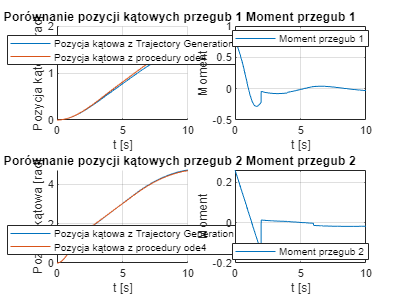

figure;
subplot(2, 2, 1);
hold on
plot(t_1, q_1)
plot(t_1, q_1_check)
hold off
legend('Pozycja kątowa z Trajectory Generation', 'Pozycja kątowa z procedury ode4', "Location","best")
title('Porównanie pozycji kątowych przegub 1')
xlabel('t [s]')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 2, 2);
plot(t_1, u_1)
legend('Moment przegub 1', "Location","best")
title('Moment przegub 1')
xlabel('t [s]')
ylabel('Moment')
grid on
axis auto

subplot(2, 2, 3);
hold on
plot(t_2, q_2)
plot(t_2, q_2_check)
hold off
legend('Pozycja kątowa z Trajectory Generation', 'Pozycja kątowa z procedury ode4', "Location","best")
title('Porównanie pozycji kątowych przegub 2')
xlabel('t [s]')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 2, 4);
plot(t_2, u_2)
legend('Moment przegub 2', "Location","best")
title('Moment przegub 2')
xlabel('t [s]')
ylabel('Moment')
grid on
axis auto

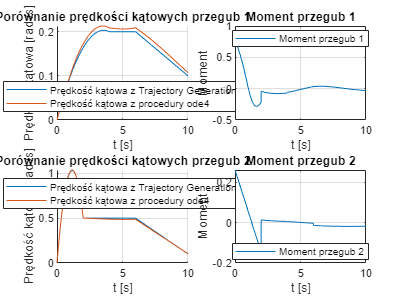

figure;
subplot(2, 2, 1);
hold on
plot(t_1, dq_1)
plot(t_1, dq_1_check)
hold off
legend('Prędkość kątowa z Trajectory Generation', 'Prędkość kątowa z procedury ode4', "Location","best")
title('Porównanie prędkości kątowych przegub 1')
xlabel('t [s]')
ylabel('Prędkość kątowa [rad /s]')
grid on
axis auto

subplot(2, 2, 2);
plot(t_1, u_1)
legend('Moment przegub 1', "Location","best")
title('Moment przegub 1')
xlabel('t [s]')
ylabel('Moment')
grid on
axis auto

subplot(2, 2, 3);
hold on
plot(t_2, dq_2)
plot(t_2, dq_2_check)
hold off
legend('Prędkość kątowa z Trajectory Generation', 'Prędkość kątowa z procedury ode4', "Location","best")
title('Porównanie prędkości kątowych przegub 2')
xlabel('t [s]')
ylabel('Prędkość kątowa [rad /s]')
grid on
axis auto

subplot(2, 2, 4);
plot(t_2, u_2)
legend('Moment przegub 2', "Location","best")
title('Moment przegub 2')
xlabel('t [s]')
ylabel('Moment')
grid on
axis auto

function [q, dq] = ode4(u, q_0, dq_0, L1, L2, m1, m2)
    
    h = 0.01;
    q(:, 1) = q_0;
    dq(:, 1) = dq_0;

    
    for i = 1:1:1000
    
        M = [(((1/3) * m1) + m2) * L1^2 + ((1/3) * m2 * L2^2) + (m2 * L1 * L2 * cos(q(2, i))), ...
        ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q(2, i))); ...
        ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q(2, i))), ...
        ((1/3) * m2 * L2^2)];
   
        C = [0, (-m2 * L1 * L2 * (dq(1, i) + (1/2) * dq(2, i)) * sin(q(2, i))); ...
        ((1/2) * m2 * L1 * L2 * dq(1, i) * sin(q(2, i))), 0];
   
        K_11 = h .* dq(:, i);
        K_12 = h .* inv(M) * (u(:, i) - C*dq(:, i));
        K_21 = h .* (dq(:, i) + K_11/2);
        K_22 = h .* (inv(M) * (u(:, i) - C*dq(:, i)) + K_12/2);
        K_31 = h .* (dq(:, i) + K_21/2);
        K_32 = h .* (inv(M) * (u(:, i) - C*dq(:, i)) + K_22/2);
        K_41 = h .* (dq(:, i)+ K_31);
        K_42 = h .* (inv(M) * (u(:, i) - C*dq(:, i)) + K_32);

        K_1 = (1/6) * (K_11 + 2*K_21 + 2*K_31 + K_41);
        K_2 = (1/6) * (K_12 + 2*K_22 + 2*K_32 + K_42);

        q(:, i + 1) = q(:,i) + K_1;
        dq(:, i + 1) = dq(:,i) + K_2;
    end
end

function [u] = dynamics_model(q1, q2, dq1, dq2, ddq1, ddq2, m1, m2, L1, L2)
   
    n = length(q1);
    for i=1:n
        A = [(((1/3) * m1) + m2) * L1^2 + ((1/3) * m2 * L2^2) + (m2 * L1 * L2 * cos(q2(i))), ...
       ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q2(i))); ...
       ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q2(i))), ...
       ((1/3) * m2 * L2^2)];
   
        B = [ddq1(i); ddq2(i)];
   
        C = [0, (-m2 * L1 * L2 * (dq1(i) + (1/2) * dq2(i)) * sin(q2(i))); ...
       ((1/2) * m2 * L1 * L2 * dq1(i) * sin(q2(i))), 0];
   
        D = [dq1(i); dq2(i)];
    
        u(:, i) = A*B + C*D;
    
    end
end

function [q,dq,ddq, t] = Trajectory_Generation(solved, q_p_in,dq_p_in,q_k_in,dq_k_in,Tk_in,Ta_in,Tb_in,dt_in,V_in)
    syms q_p q_k v
    syms t_a t_c t_k t_b
    syms dq_k dq_p
    temp = struct2cell(solved);
    val = subs(temp,{q_p, dq_p, q_k, dq_k, t_k, t_a, t_b, v},{q_p_in dq_p_in q_k_in dq_k_in Tk_in Ta_in Tb_in V_in});
    t1 = 0:dt_in:Ta_in;
    q_1 = val(1) + val(2) * t1 + val(3) * (t1).^2 + val(4) * (t1).^3;
    d_q1 = val(2) + 2*val(3)*t1 + 3*val(4) * (t1).^2;
    dd_q1 = 2*val(3) + 6*val(4)*t1;
    
    t2 = Ta_in:dt_in:(Tk_in - Tb_in);
    q_2 = val(5) + val(6) * t2;
    d_q2 = val(6) + zeros(1, length(t2));
    dd_q2 = zeros(1, length(t2));
    
    t3 = (Tk_in - Tb_in):dt_in:Tk_in;
    q_3 = val(7) + val(8) * t3 + val(9) * (t3).^2 + val(10) * (t3).^3;
    d_q3 = val(8) + 2*val(9)*t3 + 3*val(10) * (t3).^2;
    dd_q3 = 2*val(9) + 6*val(10)*t3;

    t = [0:dt_in:Tk_in];
    q = [q_1(1:end-1), q_2(1:end-1), q_3];
    dq = [d_q1(1:end-1), d_q2(1:end-1), d_q3];
    ddq = [dd_q1(1:end-1), dd_q2(1:end-1), dd_q3];
end